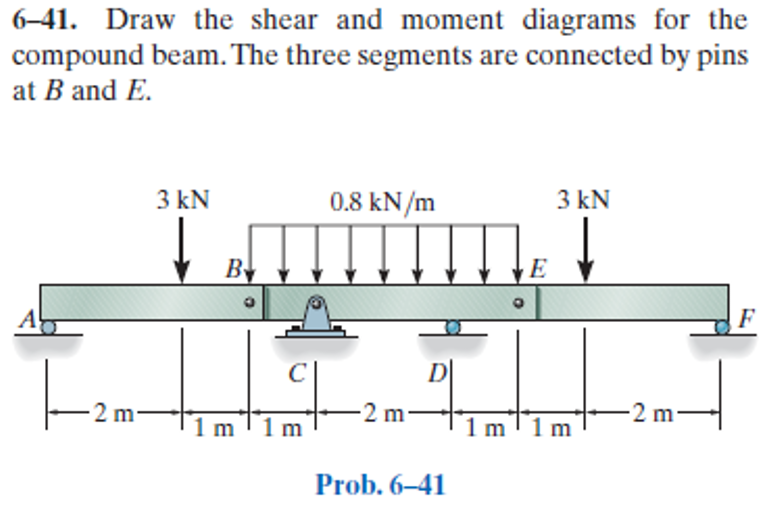

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-41P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-41P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('concentrated', 'force', -3*u.kN, 2*u.m);
b = b.add('hinge', 'force', 'Hb', 3*u.m);
b = b.add('reaction', 'force', 'Rc', 4*u.m);
b = b.add('reaction', 'force', 'Rd', 6*u.m);
b = b.add('hinge', 'force', 'He', 7*u.m);
b = b.add('concentrated', 'force', -3*u.kN, 8*u.m);
b = b.add('reaction', 'force', 'Rf', 10*u.m);
b = b.add('distributed', 'force', -0.8*u.kN/u.m, [3 7]*u.m);
b.L = 10*u.m;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{x\,\left(69\,m^{2}-5\,x^{2}\right)}{30\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\leq 2\,m\\ -\frac{10\,x^{3}-90\,x^{2}\,m+249\,x\,m^{2}-120\,m^{3}}{30\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\in \left(2\,m,3\,m\right]\\ \frac{\left(x-4\,m\right)\,\left(-x^{3}-2\,x^{2}\,m+28\,x\,m^{2}+48\,m^{3}\right)}{30\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m} & \text{ if }x\in \left(3\,m,4\,m\right]\\ -\frac{\left(x-4\,m\right)\,\left(x-6\,m\right)\,\left(x^{2}-10\,x\,m+56\,m^{2}\right)}{30\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m} & \text{ if }x\in \left(4\,m,6\,m\right]\\ -\frac{\left(x-6\,m\right)\,\left(x^{3}-32\,x^{2}\,m+312\,x\,m^{2}-872\,m^{3}\right)}{30\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m} & \text{ if }x\in \left(6\,m,7\,m\right]\\ \frac{10\,x^{3}-210\,x^{2}\,m+1449\,x\,m^{2}-3370\,m^{3}}{30\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\in \left(7\,m,8\,m\right]\\ -\frac{\left(x-10\,m\right)\,\left(5\,x^{2}-100\,x\,m+431\,m^{2}\right)}{30\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }8\,m<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{23\,m^{2}-5\,x^{2}}{10\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\leq 2\,m\\ -\frac{10\,x^{2}-60\,x\,m+83\,m^{2}}{10\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\in \left(2\,m,3\,m\right]\\ -\frac{\left(x+4\,m\right)\,\left(2\,x^{2}-11\,x\,m+8\,m^{2}\right)}{15\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m} & \text{ if }x\in \left(3\,m,4\,m\right]\\ -\frac{2\,\left(x-5\,m\right)\,\left(x^{2}-10\,x\,m+40\,m^{2}\right)}{15\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m} & \text{ if }x\in \left(4\,m,6\,m\right]\\ -\frac{\left(x-14\,m\right)\,\left(2\,x^{2}-29\,x\,m+98\,m^{2}\right)}{15\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m} & \text{ if }x\in \left(6\,m,7\,m\right]\\ \frac{10\,x^{2}-140\,x\,m+483\,m^{2}}{10\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\in \left(7\,m,8\,m\right]\\ -\frac{5\,x^{2}-100\,x\,m+477\,m^{2}}{10\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }8\,m<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} x\,\mathrm{kN} & \text{ if }x\leq 2\,m\\ -2\,\left(x-3\,m\right)\,\mathrm{kN} & \text{ if }x\in \left(2\,m,3\,m\right)\\ -\frac{2\,\left(x+2\,m\right)\,\left(x-3\,m\right)}{5}\,\frac{\mathrm{kN}}{m} & \text{ if }x\in \left[3\,m,4\,m\right]\\ -\frac{2\,\left(x^{2}-10\,x\,m+30\,m^{2}\right)}{5}\,\frac{\mathrm{kN}}{m} & \text{ if }x\in \left(4\,m,6\,m\right]\\ -\frac{2\,\left(x-7\,m\right)\,\left(x-12\,m\right)}{5}\,\frac{\mathrm{kN}}{m} & \text{ if }x\in \left(6\,m,7\,m\right]\\ 2\,\left(x-7\,m\right)\,\mathrm{kN} & \text{ if }x\in \left(7\,m,8\,m\right]\\ -\left(x-10\,m\right)\,\mathrm{kN} & \text{ if }8\,m<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} \mathrm{kN} & \text{ if }x\leq 2\,m\\ -2\,\mathrm{kN} & \text{ if }x\in \left(2\,m,3\,m\right)\\ -\frac{2\,\left(2\,x-1\,m\right)}{5}\,\frac{\mathrm{kN}}{m} & \text{ if }x\in \left[3\,m,4\,m\right]\\ -\frac{4\,\left(x-5\,m\right)}{5}\,\frac{\mathrm{kN}}{m} & \text{ if }x\in \left(4\,m,6\,m\right]\\ -\frac{2\,\left(2\,x-19\,m\right)}{5}\,\frac{\mathrm{kN}}{m} & \text{ if }x\in \left(6\,m,7\,m\right]\\ 2\,\mathrm{kN} & \text{ if }x\in \left(7\,m,8\,m\right]\\ -1\,\mathrm{kN} & \text{ if }8\,m<x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x<3\,m\\ -\frac{4}{5}\,\frac{\mathrm{kN}}{m} & \text{ if }x\in \left[3\,m,7\,m\right]\\ 0 & \text{ if }7\,m<x \end{array}\right.$$

# reactions and hinges

ra_vpa = vpa(ra) %#ok<NASGU> 

$$ra\_vpa = \left(\begin{array}{cc} \mathrm{Ra} & \mathrm{kN}\\ \mathrm{Rc} & 3.6\,\mathrm{kN}\\ \mathrm{Rd} & 3.6\,\mathrm{kN}\\ \mathrm{Rf} & \mathrm{kN} \end{array}\right)$$

ha

$$ha = \left(\begin{array}{cc} \mathrm{Hb} & 2\,\mathrm{kN}\\ \mathrm{He} & -2\,\mathrm{kN} \end{array}\right)$$

# shear and moment diagram

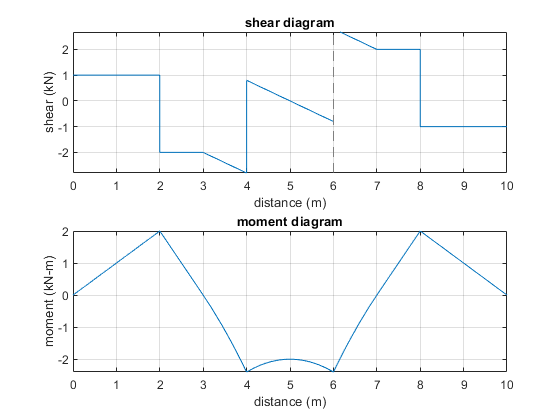

beam.shear_moment(m, v, [0 b.L], {'kN' 'm'});

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear ra_vpa;